# **Orbital Mechanics Project: Free-Return Trajectory for Earth-Moon Mission**

Code Initiation:

clc
clear
close all

set(0,'DefaultFigureWindowStyle','normal')

## Optimal Parking Orbit Altitude

For Hohmann Transfer between two circular orbits (from earth to parking orbit)

syms dVt dVp dVa ra z e
re = 6378;  % km
mu = 3.986e5;
ra = re + z

$$ra = z+6378$$

e = (ra - re)/(ra + re)

$$e = \frac{z}{z+12756}$$

dVp = sqrt(mu/re)*(sqrt(1 + e) - 1);
dVa = sqrt(mu/ra)*(1 - sqrt(1 - e));
f1 = dVt == abs(dVp) + abs(dVa);
dVt = rhs(f1);
derdVt = diff(dVt, z)

$$derdVt = \begin{array}{l} \frac{5\,\sqrt{3986}\,\left(\frac{\sigma_{3}\,\left(\bar{\sigma_{2}}-1\right)}{2\,\sigma_{2}}-\frac{\left(\sigma_{2}-1\right)\,\sigma_{1}}{2\,\bar{\sigma_{2}}}\right)\,\sigma_{4}}{\sqrt{\left(\sigma_{2}-1\right)\,\left(\bar{\sigma_{2}}-1\right)}}-\frac{\frac{4450370593380899\,\sigma_{3}\,\sigma_{5}}{1125899906842624\,\sigma_{7}}-\frac{4450370593380899\,\sigma_{1}\,\sigma_{6}}{1125899906842624\,\bar{\sigma_{7}}}}{2\,\sqrt{\sigma_{5}\,\sigma_{6}}}-\frac{5\,\sqrt{3986}\,\left|\sigma_{2}-1\right|\,\left(z+\bar{z}+12756\right)}{2\,{\left|z+6378\right|}^{2}\,\sqrt{\left(\bar{z}+6378\right)\,\left(z+6378\right)}\,\sigma_{4}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\bar{z}+12756}-\frac{\bar{z}}{{\left(\bar{z}+12756\right)}^{2}}\\ \sigma_{2}=\sqrt{1-\frac{z}{z+12756}}\\ \sigma_{3}=\frac{z}{{\left(z+12756\right)}^{2}}-\frac{1}{z+12756}\\ \sigma_{4}=\sqrt{\frac{1}{\left|z+6378\right|}}\\ \sigma_{5}=\frac{4450370593380899\,\bar{\sigma_{7}}}{562949953421312}-\frac{4450370593380899}{562949953421312}\\ \sigma_{6}=\frac{4450370593380899\,\sigma_{7}}{562949953421312}-\frac{4450370593380899}{562949953421312}\\ \sigma_{7}=\sqrt{\frac{z}{z+12756}+1} \end{array}$$

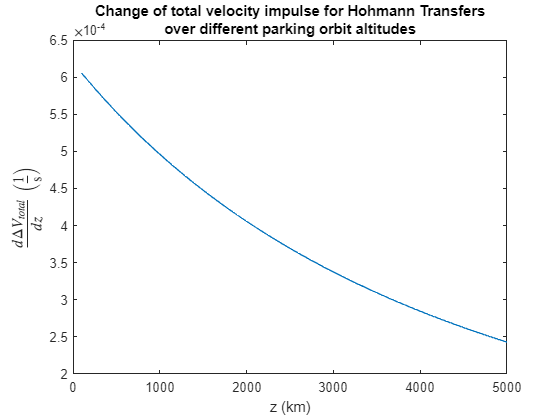

f2 = 0 == derdVt;
x = lhs(f2);
% y = subs(rhs(f2), mu, 3.986e5)
y = rhs(f2);
zs = 100:50:5000;
plot(zs, subs(y, z, zs))
title({'Change of total velocity impulse for Hohmann Transfers', 'over different parking orbit altitudes'})
xlabel('z (km)')
ylabel('$\frac{d\Delta V_{total}}{dz} \ \left(\frac{1}{\rm{s}}\right)$', Interpreter='latex')

% dVt = subs(dVt, mu, 3.986e5)
plot(zs, subs(dVt, z, zs))
% title({'Total Velocity Impulse required to perform Hohmann Transfer', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('dVt')
hold on
syms dep 
dep = (mu/2)*( (1/re) - (1/ra) )

$$dep = \frac{99650}{3189}-\frac{199300}{z+6378}$$

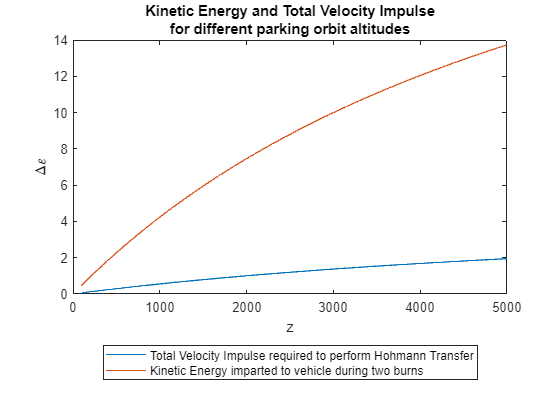

% dep = subs(dep, mu, 3.986e5)
plot(zs, subs(dep, z, zs))
title({'Kinetic Energy and Total Velocity Impulse', 'for different parking orbit altitudes'})
xlabel('z')
ylabel('$\Delta \varepsilon$', Interpreter='latex')
legend('Total Velocity Impulse required to perform Hohmann Transfer', 'Kinetic Energy imparted to vehicle during two burns', Location='southoutside')
hold off

Based on online sources, it is generally accepted that the optimal earth parking orbit is in LEO (Low Earth Orbit), which is between 160km - 2000km. Apollo 11 went into a nearly circular earth parking orbit of ~185.9 km. Since that mission was successful, a parking orbit of 190km will be used. It requires less total velocity impulse to obtain the orbit via Hohmann Transfer compared to higher LEOs, while still being high enough to avoid atmospheric drag.

So, for z = 190km, we can get $\Delta V_p$, $\Delta V_a$, and $\Delta V_{total}$

z_val = 190;    % km
dVp_val = double(subs(dVp, z, z_val));  dVa_val = double(subs(dVa, z, z_val));  dVt_val = dVp_val + dVa_val;
disp([dVp_val, dVa_val, dVt_val])

    0.0578    0.0574    0.1152



Assuming that the earth rotate counterclockwise, and 1 Sidereal Day = 86400 seconds, we can find the angular velocity of earth and thus the tangential velocity

ra_po = re + z_val

ra_po = 6568

v_po = sqrt(mu/ra_po)

v_po = 7.7903

Since c $\Delta V_p \approx \Delta V_a$, then at z = 190km, the velocity of our spacecraft is $V_e$. Since we needs a 3-hour system checkout in the parking orbit, we need to make sure that the orbit period is greater than 3 hours

sys_check = 3 * 60 * 60    % seconds

sys_check = 10800

T_po = 2*pi*sqrt((ra_po^3)/mu)  % seconds

T_po = 5.2974e+03

if (T_po > sys_check)
    disp('Proceed')
else
    disp('Spacecraft will orbit Earth more than once')
end

Spacecraft will orbit Earth more than once


Find eccentricity of transfer ellipse toward Lunar radius

rm = 1749;  % km, radius of Moon
a = re + z_val  % Semi-major axis of earth parking orbit

a = 6568

rp = a  % Perigee Radius of Transfer Ellipse

rp = 6568

rem = 384400 % Apogee Radius of Transfer Ellipse, which is approximately the distance from the earth to the moon

rm = 384400

e_em = 1 - rp/rem

e_em = 0.9829

% e_em = (rm - rp)/(rm + rp)  % Eccentricity of earth-moon transfer ellipse
a_em = rp / (1 - e_em)  % Semi-major axis of earth-moon transfer ellipse

a_em = 3.8440e+05

soi_m = (0.073e24/5.97219e24)^(2/5)*(3.844e5)   % Radius of Sphere of Influence of Moon

soi_m = 6.6018e+04

a_em = sqrt( (rem)^2 + (soi_m)^2 )

a_em = 3.9003e+05

dVp_m = sqrt(mu/rp)*(sqrt(1+e_em) - 1)

dVp_m = 3.1797

alpha = 90;    % Degrees
gamma = 12;     % Degrees
r0 = [-rp*cosd(alpha) -rp*sind(alpha)];

r0 =            0       -6568


r1 = [ rem - soi_m*cosd(gamma) soi_m*sind(gamma)];

r1 = 1.0e+05 *

    3.1983    0.1373


e = [0 0];

e =      0     0


m = [rem 0];

m =       384400           0


x = [r0(1) r1(1) e(1) m(1)]

x = 1.0e+05 *

         0    3.1983         0    3.8440


y = [r0(2) r1(2) e(2) m(2)]

y = 1.0e+04 *

   -0.6568    1.3726         0         0


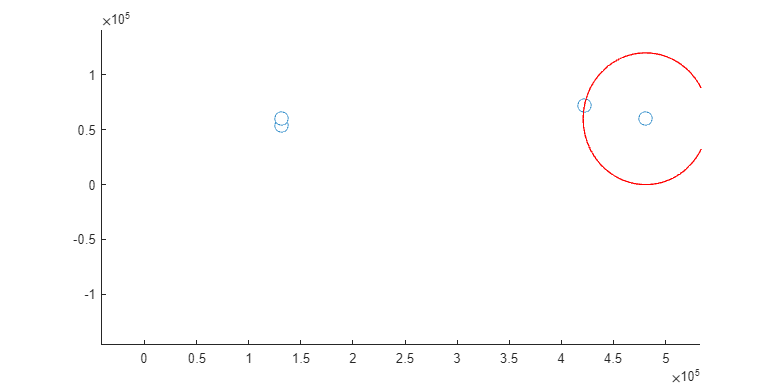

fig = figure(); 
fig.Position(3:4) = [1000, 500];
% axis([(-1.0e4)*2 (5.0e5)*2 (-1.0e4) (5.0e5)]);
hold on
plot(x, y, Marker="o", MarkerSize=10, MarkerFaceColor="auto", LineStyle="none")
t = 0: pi / 50.0: 2.0 * pi;

% plot Earth

plot(re*sin(t), re*cos(t), 'Color', 'g');
plot(rm*sin(t) + rem, rm*cos(t), 'Color', 'g');

% plot circular earth orbit

plot(rp * sin(t), rp * cos(t), 'Color', 'r');

% plot Moon SOI

plot((soi_m * sin(t)) + rem, (soi_m * cos(t)), 'Color', 'r');


rvec = r1 - r0

rvec = 1.0e+05 *

    3.1983    0.2029


% plot([r0(1) r1(1)], [r0(2) r1(2)])

